clc;
clear all;
warning off;
tic
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0      %A1
      0      %b1
      0      %A2
      0      %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub = [
      0.3       %A1
      0.2       %b1
      0.5          %A2
      0.5       %b2
      3       %Tp
      6       %Tf0
      15      %Tvl
      10      %Tv0
      0.95    %yita
     ];    

Npara = length(lb); 

A1   = 0.165         ; A2   = 0.335         ;
b1   = 0.0455        ; b2   = 0.3           ;
Tp   = 1.5           ; Tf0  = 6             ;
Tvl  = 13            ; Tv0  = 6             ;
st   = 0.19          ; yita = 0.95          ;

para_init = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

%% ==================== 1. Operating condition setup ============================
meanangle    = 15;
averageangle = 10;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

n_steps = conditions.n_steps;
w       = conditions.w;
dt      = conditions.dt;

## 4. objective function

fitnessFcn = @(param) fitness(param);
initial_fitness = fitness(para_init);
nonlcon = @(param) fitness_constraint(param, initial_fitness);

## 5. global optimization, genetic algorithm settings 

globaloptions = optimoptions('ga',    ...
    'PopulationSize', 128,      ...     % population size
    'MaxGenerations', 50,      ...     % maximum generations
    'FunctionTolerance',1e-6,   ...    
    'ConstraintTolerance',1e-6, ...  
    'PlotFcn','gaplotrange',    ...     % convergence plot
    'Display','iter',           ...   
    'InitialPopulationMatrix', para_init, ...
    'UseParallel',true);         

## 6. Run evolutionary optimization

fprintf('===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====\n'); 

===== Starting dynamic-stall BL parameter optimization [CFD fit + area similarity] =====



single objectiveoptimization:
9 variable
1 nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
using 'Processes' profilefilestarting parallel pool(parpool)...
keep ID is 1 jobs, because they contain crash dumpsfile。
you can use 'delete(myCluster.Jobs)' to delete using profilefile Processes all jobs created。to create 'myCluster', please use 'myCluster = parcluster('Processes')'。
2026-01-19 21:19:31: connected to 32 itemsin parallel pool workers 15 items。
connected to 32 itemsparallel pool of workers。

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           3132       2.87424            0      0
    2           6200       2.38399            0      0
    3           9268       2.38089            0      0
    4          12336       2.38083            0      0
   

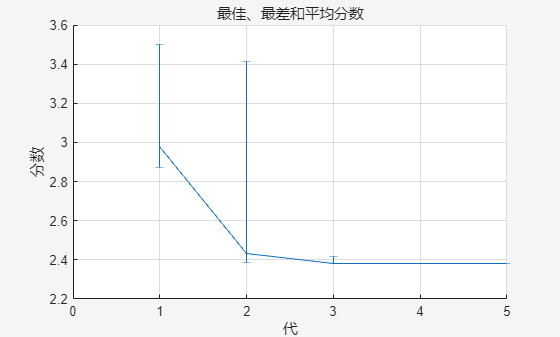

[para_global, fitness_opt] = ga(fitnessFcn, Npara, [], [], [], [], lb, ub, nonlcon, globaloptions);

fprintf('===== optimization completed！best fitness value = %.8f =====\n', fitness_opt);

===== optimization completed！best fitness value = 2.38072747 =====


## 7. local optimization

fminconOpts = optimoptions('fmincon', ...
    'Algorithm', 'interior-point', ...
    'Display', 'iter', ... 
    'MaxFunctionEvaluations', 50, ... 
    'OptimalityTolerance', 1e-8, ...
    'StepTolerance', 1e-10,...
    'PlotFcn','optimplotfirstorderopt',...
    'UseParallel',true);

## 8. Run local optimization

fprintf('===== fmincon local optimizationstart =====\n');

===== fmincon local optimizationstart =====


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      10    2.380727e+00    0.000e+00    6.224e-01
    1      20    3.221000e+00    0.000e+00    4.241e+01    3.487e-01
    2      41    3.383999e+00    0.000e+00    3.711e+01    1.453e-01
    3      56    3.385962e+00    0.000e+00    3.178e+00    1.198e-01

solver stopped prematurely。

fmincon stopped, because it exceeded the functionComputelimit, 
options.MaxFunctionEvaluations = 5.000000e+01。



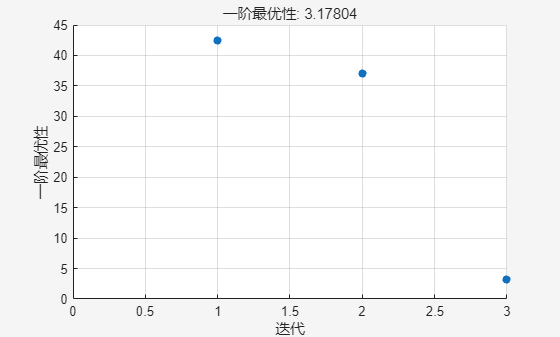

para1 = para_global;  % use GA optimum as the initial value
[para_local, f_opt] = fmincon(fitnessFcn, para1, [], [], [], [], lb, ub, nonlcon, fminconOpts);

fprintf('===== localoptimization completed:best fitness value = %.10f =====\n', f_opt);

===== localoptimization completed:best fitness value = 3.3859616612 =====


## 7. resultOutput+Save

para_label = {'A1','b1','A2','b2','Tp','Tf0','Tvl','Tv0','yita'};
fprintf('\n==================== Initial vs Optimized Parameter Comparison ====================\n');


==================== Initial vs Optimized Parameter Comparison ====================


fprintf('initial fitness=%.6f | optimized fitness=%.6f\n', fitness(para_init), fitness(para_local));

initial fitness=21.001085 | optimized fitness=3.385962


for i = 1:Npara
    fprintf('%5s : initial value=%.6f | optimized value=%.6f\n', para_label{i}, para_init(i), para_local(i));
end

   A1 : initial value=0.165000 | optimized value=0.040047
   b1 : initial value=0.045500 | optimized value=0.112948
   A2 : initial value=0.335000 | optimized value=0.488129
   b2 : initial value=0.300000 | optimized value=0.435412
   Tp : initial value=1.500000 | optimized value=2.357909
  Tf0 : initial value=6.000000 | optimized value=5.369212
  Tvl : initial value=13.000000 | optimized value=14.174294
  Tv0 : initial value=6.000000 | optimized value=9.705222
 yita : initial value=0.950000 | optimized value=0.888903


[A1,b1,A2,b2,Tp,Tf0,Tvl,Tv0,yita] = deal(para_local(:));
save('bl_cfd_final_optimized_parameters.mat','para_local','fitness_opt');
fprintf('\noptimization results saved to:bl_cfd_final_optimized_parameters.mat\n');


optimization results saved to:bl_cfd_final_optimized_parameters.mat


toc

elapsed 5164.546576 seconds。


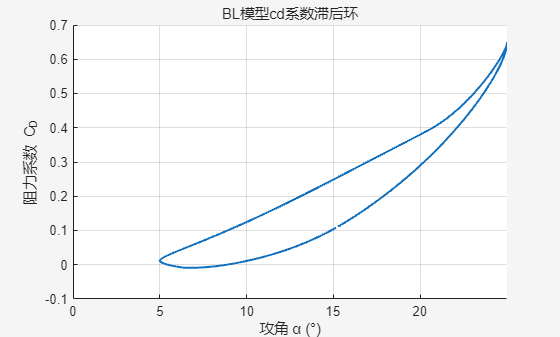

%% ===================== 2. ComputeBLmodelofOutputvalue Cl_BL / Cm_BL =====================
[CC_total,CN_total,CM_total,CD,CL,CM,a] = cal_DS(para_local,conditions,airfoildata);

% CFDdata
[a0, Cl_CFD,Cd_CFD,Cm_CFD] = get_CFDdata('FFA_W3_211_rlt_20.txt');

%% 5. Total aerodynamic-force conversion
% lift、dragconversion(trigonometric projection)

start = 7.5;
last  = 8.5;
idx_s = 2*pi/w*start/dt;
idx_l = 2*pi/w*last/dt;

plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l), 'LineWidth',1.5);
xlabel('angle of attack α (°)'); ylabel('lift coefficient C_L');
title('BLmodelclcoefficient hysteresis loop'); grid on;


plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), 'LineWidth',1.5);
xlabel('angle of attack α (°)'); ylabel('drag coefficient C_D');
title('BLmodelcdcoefficient hysteresis loop');grid on;

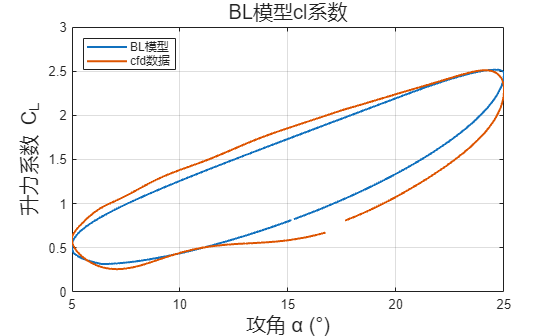


%openfastdata----------------------------------------------

fastcl = readmatrix("openfast_1hz_5_cl.txt");
fastcl(:,2) = smooth(fastcl(:,2));
fast_a1 = fastcl(:,1);
fast_cl = fastcl(:,2);

fastcd = readmatrix("openfast_1hz_5_cd.txt");
fastcd(:,2) = smooth(fastcd(:,2));
fast_a2 = fastcd(:,1);
fast_cd = fastcd(:,2);

%CFDdata---------------------------------------------------
data = readmatrix("FFA_W3_211.txt");
figure
[a1,cl] = drawCoffeint('cl_211_0.31_20.out',meanangle,averageangle);
plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l),a1,cl, 'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('lift coefficient C_L','FontSize',15);
title('BLmodelclcoefficient','FontSize',15); grid on;
legend('BLmodel','cfddata','Location','northwest')
saveas(gcf, ['cl_compare','.png']);
exportgraphics(gcf,'cl_compare.pdf','ContentType', 'vector')

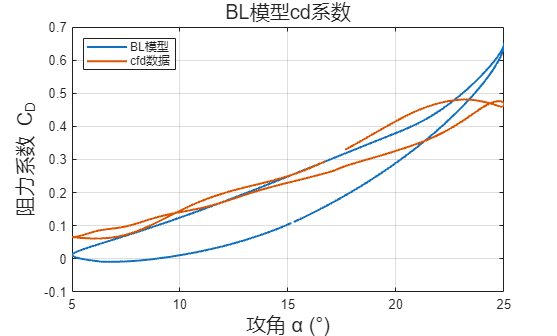


figure
[a2,cd] = drawCoffeint('cd_211_0.31_20.out',meanangle,averageangle);
plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), a2,cd,'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('drag coefficient C_D','FontSize',15);
title('BLmodelcdcoefficient','FontSize',15); grid on;
legend('BLmodel','cfddata','Location','northwest')
saveas(gcf, ['cd_compare','.png']);
exportgraphics(gcf,'cd_compare.pdf','ContentType', 'vector')


% figure
% [a3,cm] = drawCoffeint('cm_211_0.31_20.out',meanangle,averageangle);
% plot(rad2deg(a(idx_s:idx_l)), CM_total(idx_s:idx_l),data(43:72,1),data(43:72,4),a3,cm, 'LineWidth',1.5);
% xlabel('angle of attack α (°)','FontSize',15); 
% ylabel('moment coefficient C_M','FontSize',15);
% title('BLmodelcmcoefficient','FontSize',15); grid on;
% legend('BLmodel','lift-drag data','CFDresult','Location','northwest')
% saveas(gcf, ['cm_compare','.png']);
% exportgraphics(gcf,'cm_compare.pdf','ContentType', 'vector')

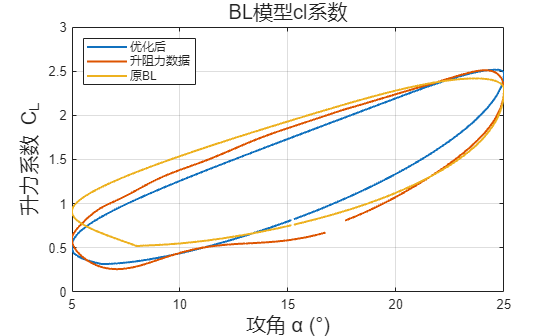

[CC_init,CN_init,CM_init,CD_init,CL_init,CM_init,a_init] = cal_DS(para_init,conditions,airfoildata,st);

figure
plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l),a1,cl,rad2deg(a_init(idx_s:idx_l)),CL_init(idx_s:idx_l), 'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('lift coefficient C_L','FontSize',15);
title('BLmodelclcoefficient','FontSize',15); grid on;
legend('optimized','lift-drag data','original BL','Location','northwest')

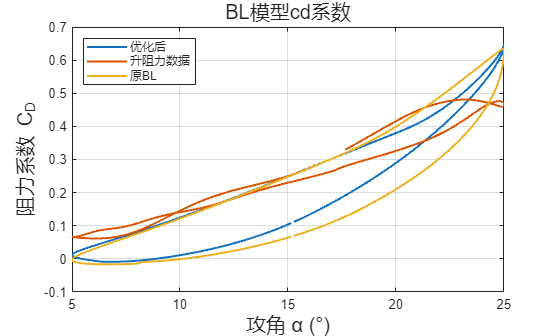


figure
plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), a2,cd,rad2deg(a_init(idx_s:idx_l)),CD_init(idx_s:idx_l),'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('drag coefficient C_D','FontSize',15);
title('BLmodelcdcoefficient','FontSize',15); grid on;
legend('optimized','lift-drag data','original BL','openfast','Location','northwest')